% Just loading up the values that SEEM like theyre correct.
load('sim_data_single.mat')
c = 3e8; % m/s

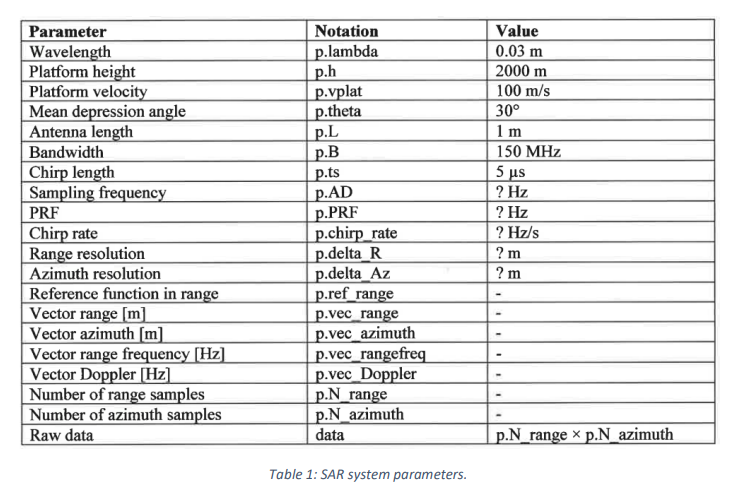

# Question 1 - SAR Signal Simulator

1) Determine the sampling frequency to avoid range ambiguities and the PRF to avoid azimuth ambiguities due to sub-sampling. Give theoretical resolutions in range and azimuth (hint: use IQ sampling)

base_frequency = c/p.lambda % Around 10 GHz

base_frequency = 1.0000e+10

The range is determined by the angle of the beam plus half its width along the ground (Recall Tristyn's drawings). Obviously the width is perpindicular to the beam radius and not along the ground, so some trig is needed.

beam_centre_length = p.h / sin(p.theta)

beam_centre_length = 4.0000e+03


% max_range = find length plus width thing and then take that shit and find
% the hypoteneus of it

If the antenna's aperture is in the direction of the platform's motion that means this aperture value (p.L) lets us find the width of the beam and thus the outer bounds of the illuminated area

beam_width = 0.89 * p.lambda / p.L

beam_width = 0.0267

% By taking the maximum in one direction from the mean beam depression, we
% find the maximum range as the hypotenues of that new triangle
max_range = p.h / sin(p.theta - beam_width/2)

max_range = 4.0951e+03

Max unambiguous range is $R_{max} = \frac{c}{2 \cdot PRF} = \frac{c \cdot PRI}{2}$, and recall that $\Delta R = \frac{c}{2B}$

% So
PRF_min = c / (2 * max_range) % Increasing Rmax means decreasing PRF

PRF_min = 3.6630e+04

p.delta_R = c/(2*p.B) % I mean this makes sense

p = struct with fields:
         lambda: 0.0300
              h: 2000
          vplat: 100
          theta: 0.5236
              L: 1
              B: 150000000
             ts: 5.0000e-06
             AD: 165000000
            PRF: 400
     chirp_rate: 3.0000e+13
        delta_R: 1
       delta_Az: 0.5000
      ref_range: [908×1 double]
      slow_time: 2.6400
    vec_azimuth: [-132.0000 -131.7500 -131.5000 -131.2500 -131.0000 -130.7500 -130.5000 -130.2500 -130.0000 -129.7500 -129.5000 -129.2500 -129.0000 -128.7500 -128.5000 -128.2500 -128.0000 -127.7500 -127.5000 -127.2500 -127.0000 … ] (1×1057 double)
      vec_range: [7200 7.2009e+03 7.2018e+03 7.2027e+03 7.2036e+03 7.2045e+03 7.2055e+03 7.2064e+03 7.2073e+03 7.2082e+03 7.2091e+03 7210 7.2109e+03 7.2118e+03 7.2127e+03 7.2136e+03 7.2145e+03 7.2155e+03 7.2164e+03 7.2173e+03 … ] (1×1761 double)



% azimuth resolution is apparently 1/length of antenna?
% Range resolution = fixed
% PRF gives us max range (unambiguous)
% PRF gives max measurable doppler ĸ
% Can sample at B because of downsampling and IQ